%% SMA Assignment 3 – Live Script (Friends' code only: InterplanetaryTransfers)
clear; clc; close all;

%% Make sure class is visible
addpath(pwd);
assert(~isempty(which("InterplanetaryTransfers")), "InterplanetaryTransfers.m not found on MATLAB path!");

%% Files (Horizons)
earthFile = "data/earth_data.txt";
marsFile  = "data/mars_data.txt";

%% Constants in AU / year
muSun  = 4*pi^2;        % AU^3/yr^2
yr_day = 365.24217;     % used in their parser if output_year="year"

%% Load ephemerides (AU, AU/yr)
E = InterplanetaryTransfers.parse_horizon_file(earthFile, "year");
M = InterplanetaryTransfers.parse_horizon_file(marsFile,  "year");

% Quick sanity
fprintf("Earth ephemerides: %d rows (%s .. %s)\n", height(E), string(E.Date(1)), string(E.Date(end)));

Earth ephemerides: 41 rows (01-Jun-2030 .. 24-Sep-2031)


fprintf("Mars  ephemerides: %d rows (%s .. %s)\n", height(M), string(M.Date(1)), string(M.Date(end)));

Mars  ephemerides: 43 rows (01-Sep-2030 .. 19-Dec-2032)



%% Lambert solver parameters (friends' interface)
lsp.mu            = muSun;
lsp.factors       = [1.0001; 1.2];   % initial guess factors for a_m
lsp.max_iterations= 60;
lsp.tolerance     = 1e-10;

ipt = InterplanetaryTransfers;

%% Prepare rotation vector for signed angle (defines direction)
rotvec = cross(E.Position(1,:), E.Position(2,:)).';  % 3x1

%% Allocate grids
nDep = height(E);
nArr = height(M);

C3_dep_AU2yr2   = nan(nDep,nArr);  % C3 at departure (AU^2/yr^2)
vinf_arr_AUyr   = nan(nDep,nArr);  % v_inf at arrival (AU/yr)
TOF_days        = nan(nDep,nArr);  % time of flight (days)

% Optional: also store friends' metric (sum of v_inf magnitudes)
DVsum_AUyr      = nan(nDep,nArr);

%% Loop over date grid
for i = 1:nDep
    r1 = E.Position(i,:).';   % AU
    vE = E.Velocity(i,:).';   % AU/yr

    for j = 1:nArr
        dt_yr = years(M.Date(j) - E.Date(i));   % IMPORTANT: arrival - departure
        if dt_yr <= 0
            continue
        end

        r2 = M.Position(j,:).';  % AU
        vM = M.Velocity(j,:).';  % AU/yr

        % Signed transfer angle (0..2pi)
        dtheta = InterplanetaryTransfers.angle_between_vectors(r1,r2,rotvec);

        % Lambert (friends)
        [v1, v2, ~] = ipt.solve_lamberts_problem_secant( ...
            r1, r2, dtheta, dt_yr, lsp.mu, lsp.factors, lsp.max_iterations, lsp.tolerance);

        % Hyperbolic excess velocities
        vinf_dep = v1 - vE;        % AU/yr
        vinf_arr = v2 - vM;        % AU/yr

        % Outputs
        C3_dep_AU2yr2(i,j) = dot(vinf_dep, vinf_dep);
        vinf_arr_AUyr(i,j) = norm(vinf_arr);
        TOF_days(i,j)      = dt_yr * yr_day;

        DVsum_AUyr(i,j)    = norm(vinf_dep) + norm(vinf_arr);
    end

    if mod(i,25)==0 || i==1 || i==nDep
        fprintf("Progress: %d / %d departure rows\n", i, nDep);
    end
end

Progress: 1 / 41 departure rows


Progress: 25 / 41 departure rows


Progress: 41 / 41 departure rows



%% Convert for nicer plotting (optional): AU/yr -> km/s, C3 -> km^2/s^2
AU_km  = 149597870.700;
day_s  = 86400.0;
AUyr_to_kms = AU_km/(yr_day*day_s);

C3_km2s2   = C3_dep_AU2yr2 * (AUyr_to_kms^2);
vinf_kms   = vinf_arr_AUyr * AUyr_to_kms;
DVsum_kms  = DVsum_AUyr * AUyr_to_kms;

%% Find minima (ignoring NaNs)
[minC3, idxC3] = min(C3_km2s2(:),[],'omitnan');
[iC3, jC3] = ind2sub(size(C3_km2s2), idxC3);

[minVinf, idxV] = min(vinf_kms(:),[],'omitnan');
[iV, jV] = ind2sub(size(vinf_kms), idxV);

[minDV, idxDV] = min(DVsum_kms(:),[],'omitnan');
[iDV, jDV] = ind2sub(size(DVsum_kms), idxDV);

fprintf("\n==== Minima ====\n");


==== Minima ====


fprintf("Min C3_dep:  %.6g km^2/s^2 at dep %s, arr %s\n", minC3,  string(E.Date(iC3)), string(M.Date(jC3)));

Min C3_dep:  8.20722 km^2/s^2 at dep 20-Feb-2031, arr 14-Jan-2032


fprintf("Min v_inf_arr: %.6g km/s     at dep %s, arr %s\n", minVinf, string(E.Date(iV)),  string(M.Date(jV)));

Min v_inf_arr: 3.40998 km/s     at dep 22-Dec-2030, arr 06-Oct-2031


fprintf("Min (|vinf_dep|+|vinf_arr|): %.6g km/s at dep %s, arr %s\n", minDV, string(E.Date(iDV)), string(M.Date(jDV)));

Min (|vinf_dep|+|vinf_arr|): 6.7191 km/s at dep 22-Dec-2030, arr 06-Oct-2031


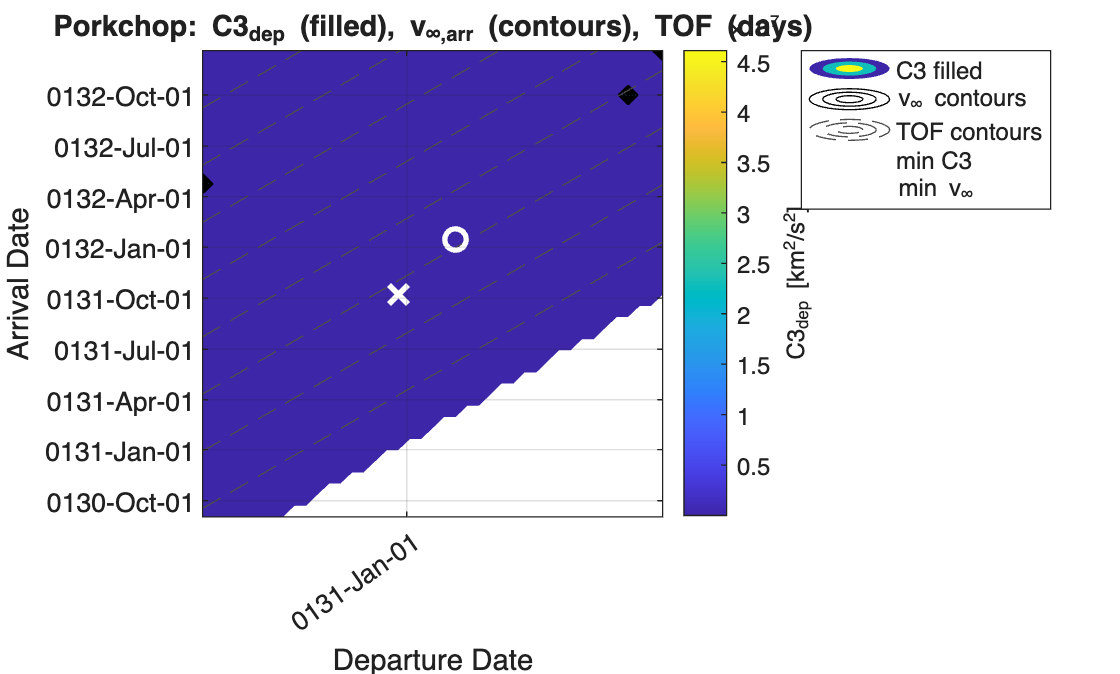


%% Porkchop plot 1: C3_dep filled + v_inf_arr contours + TOF isolines
x = convertTo(E.Date,"excel");
y = convertTo(M.Date,"excel");

figure('Name','Porkchop: C3dep + vinf_arr + TOF');
contourf(x, y, C3_km2s2.', 25, 'LineColor','none'); hold on;
grid on; box on;
cb = colorbar; ylabel(cb,"C3_{dep} [km^2/s^2]");
xlabel("Departure Date"); ylabel("Arrival Date");
title("Porkchop: C3_{dep} (filled), v_{\infty,arr} (contours), TOF (days)");

% v_inf arrival contours
A = vinf_kms(isfinite(vinf_kms));
if ~isempty(A)
    levV = linspace(min(A), max(A), 12);
    contour(x, y, vinf_kms.', levV, 'LineColor','k', 'LineStyle','-');
end

% TOF isolines
T = TOF_days(isfinite(TOF_days));
if ~isempty(T)
    levT = linspace(min(T), max(T), 10);
    contour(x, y, TOF_days.', levT, 'LineColor',[1 1 1]*0.3, 'LineStyle','--');
end

datetick('x','yyyy-mmm-dd','keeplimits'); xtickangle(35);
datetick('y','yyyy-mmm-dd','keeplimits');

% Mark minima
plot(x(iC3), y(jC3), 'wo', 'MarkerSize',8, 'LineWidth',2);
plot(x(iV),  y(jV),  'wx', 'MarkerSize',10,'LineWidth',2);

legend({'C3 filled','v_\infty contours','TOF contours','min C3','min v_\infty'}, 'Location','bestoutside');
hold off;

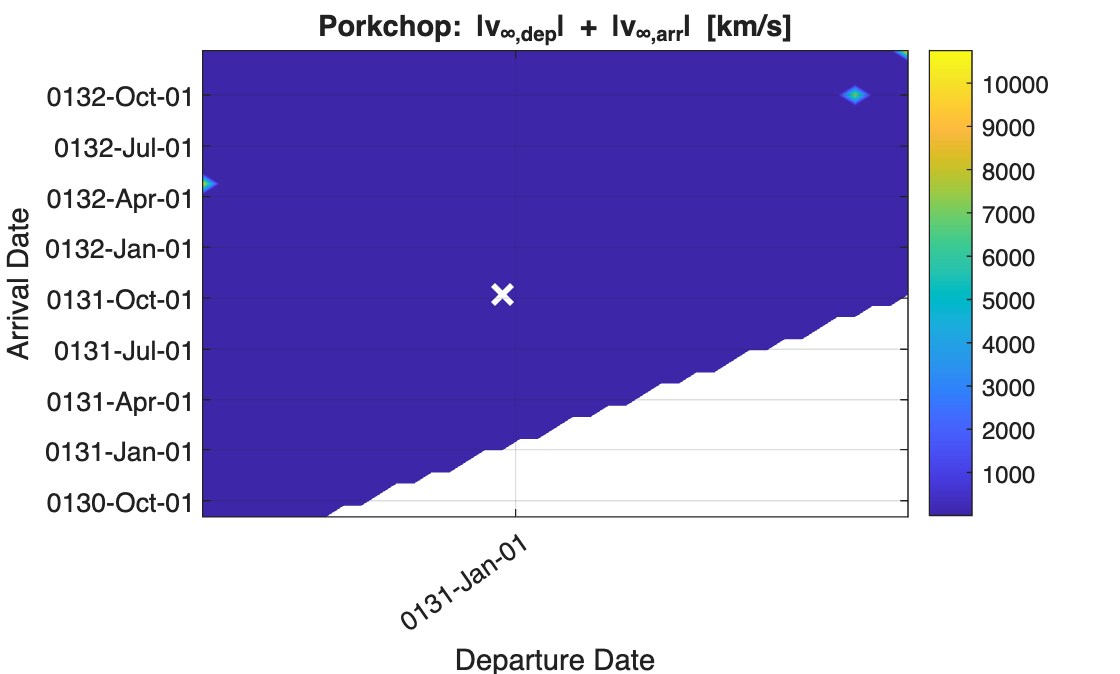


%% Porkchop plot 2 (optional): friends' delta-v-like metric (sum of vinfs)
figure('Name','Porkchop: |vinf_dep|+|vinf_arr|');
contourf(x, y, DVsum_kms.', 30, 'LineColor','none'); 
grid on; box on; colorbar;
xlabel("Departure Date"); ylabel("Arrival Date");
title("Porkchop: |v_{\infty,dep}| + |v_{\infty,arr}| [km/s]");
datetick('x','yyyy-mmm-dd','keeplimits'); xtickangle(35);
datetick('y','yyyy-mmm-dd','keeplimits');
hold on;
plot(x(iDV), y(jDV), 'wx', 'MarkerSize',10,'LineWidth',2);
hold off;